# Classification of linearly separable data with a perceptron

The exercise demonstrates an application of a perceptron for the classification of 2-dimensional data.

For this purpose, two clusters of data, belonging to two classes, are defined in 2-dimensional input space. 

The task is to construct a perceptron for the classification of data into two classes.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define input and output data

In this section, 2-dimensional data, belonging to two classes, are generated. You can modify data-generating parameters (Nclass, offset).

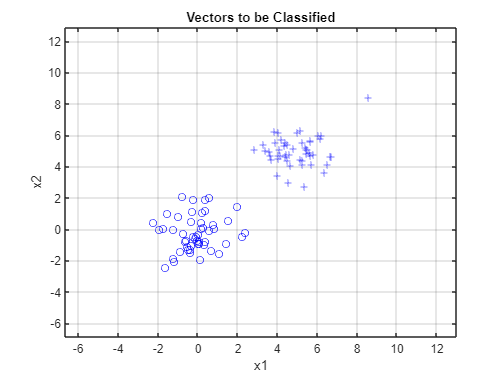

close all, clear all, clc, format compact

Nclass =50; % number of samples of each class
offset =5; % offset for second class

% define inputs and outputs
x = [randn(2,Nclass) randn(2,Nclass)+offset]; % inputs (x1,x2)
y = [zeros(1,Nclass) ones(1,Nclass)];         % outputs

% Plot input samples with PLOTPV (Plot perceptron input/target vectors)
plotpv(x,y);
xlabel('x1')
ylabel('x2')
grid on

Plot samples of each class 

## Create and train a perceptron

Use the built-in MATLAB function 'perceptron' to construct a perceptron, and train it on input/output data by using the function 'train'.

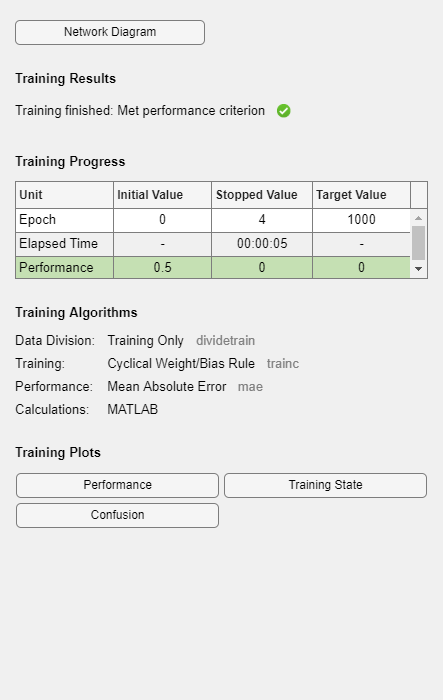

% create perceptron
net = perceptron;

% train perceptron
net = train(net,x,y);

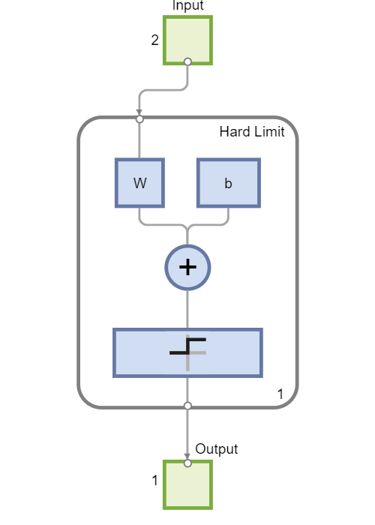

% show perceptron
view(net);

## Plot decision boundary

Show the decision boundary by which the constructed perceptron divides the input space into two regions (two classes).

Notice that sometimes the decision boundary is not very optimal but if the classes are linearly separable, the perceptron will converge to a solution.

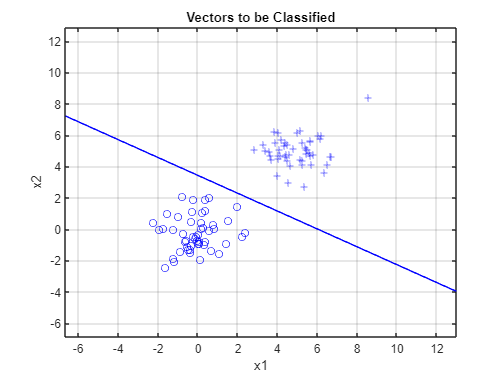

figure(1)
plotpc(net.IW{1},net.b{1});

% close all windows
close all force

## PowerPoint presentation

[NN3a_Perceptron_and_Adaline.pptx](matlab:open('./NN3a_Perceptron_and_Adaline.pptx'))